srcDir = "..\srcImages\";

barbara = readraw(srcDir + "barbara.raw");

    "→Retrieving Image "    "..\srcImages\barbara.raw"    " ..."



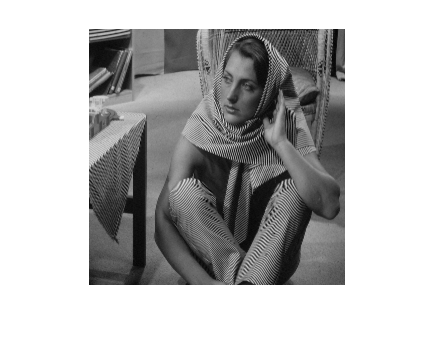

imshow(barbara);

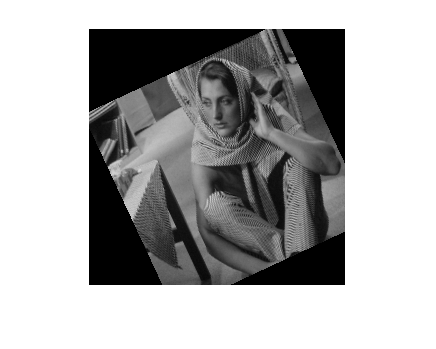


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 5);
imshow(affectedBarbara);

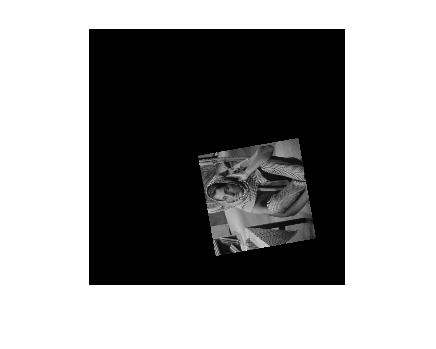


affectedBarbara = applyGeometryEffect(barbara, 3, 5, 2, 20);
imshow(affectedBarbara);

baboon = readraw(srcDir + "baboon.raw");

    "→Retrieving Image "    "..\srcImages\baboon.raw"    " ..."



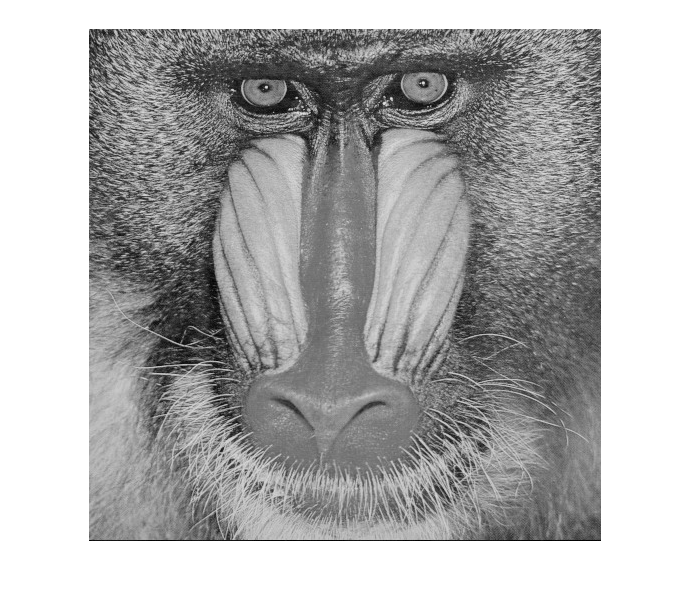

imshow(baboon);

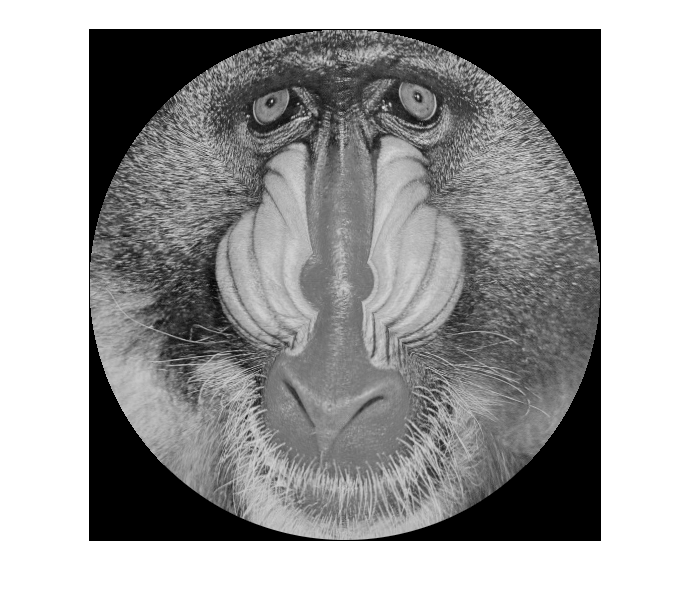


diskBaboon = toDisk(baboon);
imshow(diskBaboon);

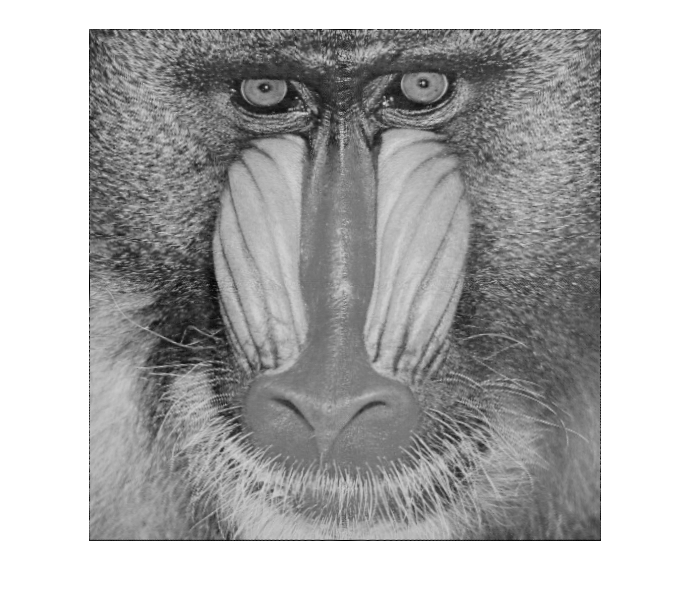


resquaredBaboon = fromDisk(diskBaboon);
imshow(resquaredBaboon);


%diskBaboon = warp(barbara, inverseDisk(128.5));
%imshow(diskBaboon);

%resquaredBaboon = fromDisk(baboon);
%imshow(resquaredBaboon);
%imshow(toDisk(resquaredBaboon));

txClasses = zeros(64, 64, 15);
for i = 1:15
    txClasses(:, :, i) = readraw(srcDir + "sample" + string(i) + ".raw");
end

    "→Retrieving Image "    "..\srcImages\sample1.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample2.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample3.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample4.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample5.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample6.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample7.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample8.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample9.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample10.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample11.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample12.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample13.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample14.raw"    " ..."

    "→Retrieving Image "    "..\srcImages\sample15.raw"    " ..."




classes = classifyLawsSmallTextures(txClasses, 5);

mosaic1 = readraw(srcDir + "comb1.raw");
imshow(mosaic1);
clustered = clusterTextures(mosaic1, [0, 63, 127, 191, 255]);
imshow(clustered);
segmented = segmentClusters(clustered, [0, 63, 127, 191, 255]);
imshow(segmented);

mosaic2 = readraw(srcDir + "comb2.raw");

    "→Retrieving Image "    "..\srcImages\comb2.raw"    " ..."



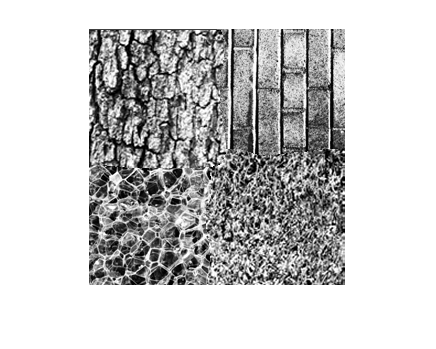

imshow(mosaic2);

clustered = clusterTextures(mosaic2, [0, 85, 170, 255]);

cluster error is 1818854.0215
cluster error is 1818853.9095
cluster error is 1818853.9095
cluster error is 1818853.9058
cluster error is 1818853.9095


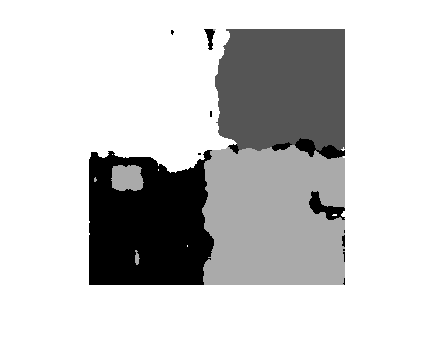

imshow(clustered);

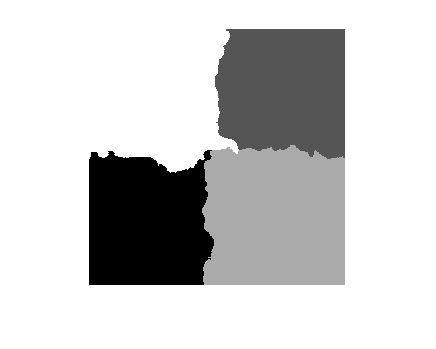

segmented = segmentClusters(clustered, [0, 85, 170, 255]);
imshow(segmented);

colors = [0, 85, 170, 255];
connectedParts = connectedComponents(segmented2);
frequencyList = frequencies(connectedParts);
keptComponents = largestComponents(segmented2, connectedParts, [0, 85, 170, 255], frequencyList);
segmented = mergeComponents(connectedParts, frequencyList, keptComponents);
[rows, cols] = size(connectedParts);
for row = 1:rows
    for col = 1:cols
        for i = 1:4
            if segmented(row, col) == keptComponents(i)
                segmented(row, col) = colors(i);
            end
        end
    end
end
imshow(uint8(segmented));

training = toGrayScale(readraw_color(srcDir + "training.raw"));

    "→Retrieving Image "    "..\srcImages\training.raw"    " ..."



test1 = toGrayScale(readraw_color(srcDir + "test1.raw"));

    "→Retrieving Image "    "..\srcImages\test1.raw"    " ..."



test2 = readraw(srcDir + "test2.raw");

    "→Retrieving Image "    "..\srcImages\test2.raw"    " ..."



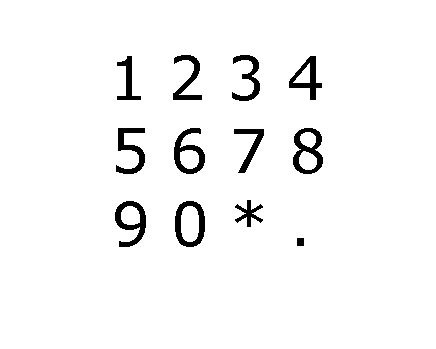

imshow(training);

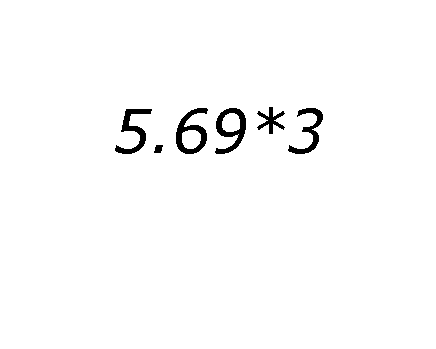

imshow(test1);

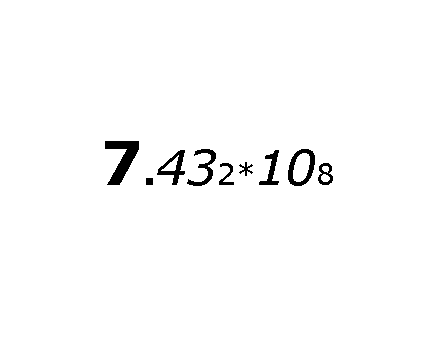

imshow(test2);

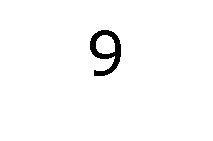

ans =   OcrFeatures with properties:

                area: 608
           perimeter: 280
            eulerNum: 0
         circularity: 0.0975
    spatialMomentRow: 5
    spatialMomentCol: 8
           symmetryX: 346
           symmetryY: 520
         aspectRatio: 1.4545


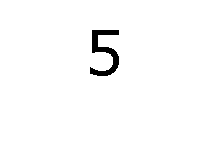

ans =   OcrFeatures with properties:

                area: 564
           perimeter: 244
            eulerNum: 1
         circularity: 0.1190
    spatialMomentRow: 5
    spatialMomentCol: 8
           symmetryX: 510
           symmetryY: 636
         aspectRatio: 1.5484


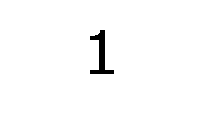

ans =   OcrFeatures with properties:

                area: 374
           perimeter: 154
            eulerNum: 1
         circularity: 0.1982
    spatialMomentRow: 6
    spatialMomentCol: 10
           symmetryX: 88
           symmetryY: 232
         aspectRatio: 1.7692


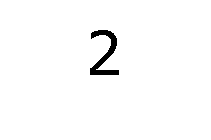

ans =   OcrFeatures with properties:

                area: 492
           perimeter: 238
            eulerNum: 1
         circularity: 0.1091
    spatialMomentRow: 5
    spatialMomentCol: 8
           symmetryX: 462
           symmetryY: 502
         aspectRatio: 1.5161


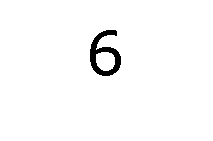

ans =   OcrFeatures with properties:

                area: 609
           perimeter: 280
            eulerNum: 0
         circularity: 0.0976
    spatialMomentRow: 5
    spatialMomentCol: 8
           symmetryX: 348
           symmetryY: 518
         aspectRatio: 1.4545


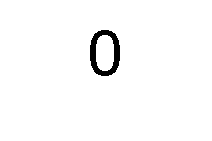

ans =   OcrFeatures with properties:

                area: 601
           perimeter: 260
            eulerNum: 0
         circularity: 0.1117
    spatialMomentRow: 5
    spatialMomentCol: 8
           symmetryX: 2
           symmetryY: 2
         aspectRatio: 1.5000


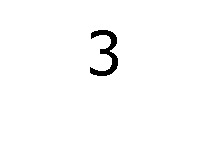

ans =   OcrFeatures with properties:

                area: 487
           perimeter: 242
            eulerNum: 1
         circularity: 0.1045
    spatialMomentRow: 5
    spatialMomentCol: 9
           symmetryX: 486
           symmetryY: 206
         aspectRatio: 1.6000


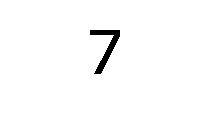

ans =   OcrFeatures with properties:

                area: 410
           perimeter: 188
            eulerNum: 1
         circularity: 0.1458
    spatialMomentRow: 6
    spatialMomentCol: 8
           symmetryX: 436
           symmetryY: 596
         aspectRatio: 1.4375


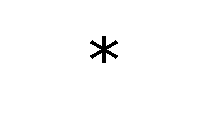

ans =   OcrFeatures with properties:

                area: 290
           perimeter: 202
            eulerNum: 1
         circularity: 0.0893
    spatialMomentRow: 9
    spatialMomentCol: 9
           symmetryX: 0
           symmetryY: 0
         aspectRatio: 1.0345


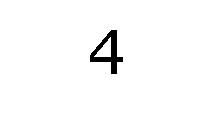

ans =   OcrFeatures with properties:

                area: 521
           perimeter: 228
            eulerNum: 0
         circularity: 0.1259
    spatialMomentRow: 6
    spatialMomentCol: 7
           symmetryX: 532
           symmetryY: 378
         aspectRatio: 1.3143


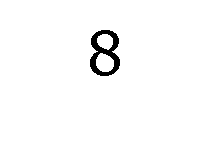

ans =   OcrFeatures with properties:

                area: 646
           perimeter: 318
            eulerNum: -1
         circularity: 0.0803
    spatialMomentRow: 5
    spatialMomentCol: 8
           symmetryX: 104
           symmetryY: 276
         aspectRatio: 1.5000


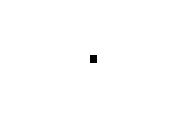

ans =   OcrFeatures with properties:

                area: 56
           perimeter: 30
            eulerNum: 1
         circularity: 0.7819
    spatialMomentRow: 26
    spatialMomentCol: 28
           symmetryX: 0
           symmetryY: 0
         aspectRatio: 1.1111



hullBounds = convexHullsFor(training);
[hulls, ~] = size(hullBounds);
for i = 1:hulls
    figure;
    convexHull = binaryImgForBounds(training, hullBounds(i, :));
    imshow(fromBinary(convexHull));
    ocrFeaturesForHull(convexHull)
end

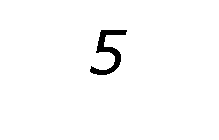

ans =   OcrFeatures with properties:

                area: 544
           perimeter: 246
            eulerNum: 1
         circularity: 0.1130
    spatialMomentRow: 5
    spatialMomentCol: 7
           symmetryX: 686
           symmetryY: 778
         aspectRatio: 1.2051


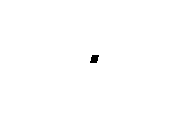

ans =   OcrFeatures with properties:

                area: 56
           perimeter: 34
            eulerNum: 1
         circularity: 0.6088
    spatialMomentRow: 26
    spatialMomentCol: 23
           symmetryX: 16
           symmetryY: 16
         aspectRatio: 1.1000


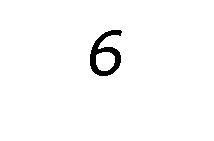

ans =   OcrFeatures with properties:

                area: 616
           perimeter: 284
            eulerNum: 0
         circularity: 0.0960
    spatialMomentRow: 5
    spatialMomentCol: 8
           symmetryX: 488
           symmetryY: 828
         aspectRatio: 1.4118


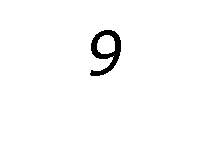

ans =   OcrFeatures with properties:

                area: 600
           perimeter: 282
            eulerNum: 0
         circularity: 0.0948
    spatialMomentRow: 5
    spatialMomentCol: 8
           symmetryX: 472
           symmetryY: 796
         aspectRatio: 1.4545


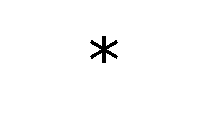

ans =   OcrFeatures with properties:

                area: 288
           perimeter: 202
            eulerNum: 1
         circularity: 0.0887
    spatialMomentRow: 9
    spatialMomentCol: 9
           symmetryX: 4
           symmetryY: 8
         aspectRatio: 1.0345


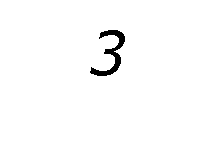

ans =   OcrFeatures with properties:

                area: 488
           perimeter: 254
            eulerNum: 1
         circularity: 0.0951
    spatialMomentRow: 5
    spatialMomentCol: 7
           symmetryX: 714
           symmetryY: 556
         aspectRatio: 1.2973



hullBounds = convexHullsFor(test1);
[hulls, ~] = size(hullBounds);
for i = 1:hulls
    figure;
    convexHull = binaryImgForBounds(test1, hullBounds(i, :));
    imshow(fromBinary(convexHull));
    ocrFeaturesForHull(convexHull)
end

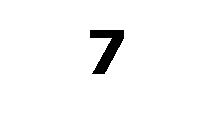

ans =   OcrFeatures with properties:

                area: 717
           perimeter: 196
            eulerNum: 1
         circularity: 0.2345
    spatialMomentRow: 6
    spatialMomentCol: 7
           symmetryX: 610
           symmetryY: 754
         aspectRatio: 1.2778


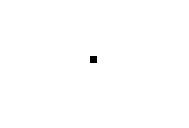

ans =   OcrFeatures with properties:

                area: 49
           perimeter: 28
            eulerNum: 1
         circularity: 0.7854
    spatialMomentRow: 28
    spatialMomentCol: 28
           symmetryX: 0
           symmetryY: 0
         aspectRatio: 1


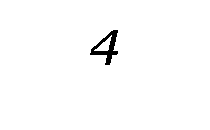

ans =   OcrFeatures with properties:

                area: 349
           perimeter: 208
            eulerNum: 0
         circularity: 0.1014
    spatialMomentRow: 7
    spatialMomentCol: 9
           symmetryX: 394
           symmetryY: 378
         aspectRatio: 1.2333


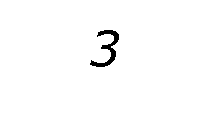

ans =   OcrFeatures with properties:

                area: 330
           perimeter: 208
            eulerNum: 1
         circularity: 0.0959
    spatialMomentRow: 7
    spatialMomentCol: 8
           symmetryX: 476
           symmetryY: 384
         aspectRatio: 1.2581


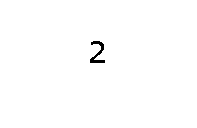

ans =   OcrFeatures with properties:

                area: 134
           perimeter: 116
            eulerNum: 1
         circularity: 0.1251
    spatialMomentRow: 11
    spatialMomentCol: 15
           symmetryX: 110
           symmetryY: 124
         aspectRatio: 1.4118


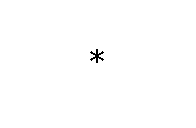

ans =   OcrFeatures with properties:

                area: 76
           perimeter: 100
            eulerNum: 1
         circularity: 0.0955
    spatialMomentRow: 16
    spatialMomentCol: 16
           symmetryX: 0
           symmetryY: 0
         aspectRatio: 1


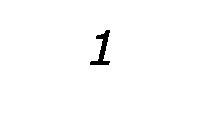

ans =   OcrFeatures with properties:

                area: 266
           perimeter: 138
            eulerNum: 1
         circularity: 0.1755
    spatialMomentRow: 7
    spatialMomentCol: 12
           symmetryX: 288
           symmetryY: 266
         aspectRatio: 1.6818


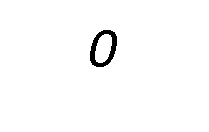

ans =   OcrFeatures with properties:

                area: 408
           perimeter: 220
            eulerNum: 0
         circularity: 0.1059
    spatialMomentRow: 7
    spatialMomentCol: 9
           symmetryX: 464
           symmetryY: 464
         aspectRatio: 1.3448


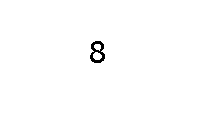

ans =   OcrFeatures with properties:

                area: 166
           perimeter: 148
            eulerNum: -1
         circularity: 0.0952
    spatialMomentRow: 11
    spatialMomentCol: 15
           symmetryX: 20
           symmetryY: 84
         aspectRatio: 1.4118



hullBounds = convexHullsFor(test2);
[hulls, ~] = size(hullBounds);
for i = 1:hulls
    figure;
    convexHull = binaryImgForBounds(test2, hullBounds(i, :));
    imshow(fromBinary(convexHull));
    ocrFeaturesForHull(convexHull)
end